%{
saveW= out.Kg(:,1);
saveV = out.Voltage(:,1);
save("g10500","saveV","saveW");
%}


alldata = ["g0.mat","g500.mat","g1000.mat","g1500.mat","g2000.mat","g2500.mat","g3000.mat","g3500.mat","g4000.mat","g4500.mat","g5000.mat","g5500.mat","g6000.mat","g6500.mat","g7000.mat","g7500.mat","g8000.mat","g8500.mat","g9000.mat","g9500.mat","g10000.mat","g10500.mat"];

dataV = [];
dataW = [];

for i = 1:22
    load(alldata(i),"saveV","saveW");
    %Get a raw data

    sumW=0;
    sumV=0;
    for j = 1:101
        sumV = sumV + saveV(j);
        sumW = sumW + saveW(j);
    end
    %Sum a data
    
    avgV = sumV / 101;
    avgW = sumW / 101;
    %Get an average

    dataW(i) = avgW;
    dataV(i) = avgV;
    %Get the data in matrix
end
%}




% Load the data
alldata = {"dataV","dataW"}

alldata = 1×2 cell array
    {["dataV"]}    {["dataW"]}


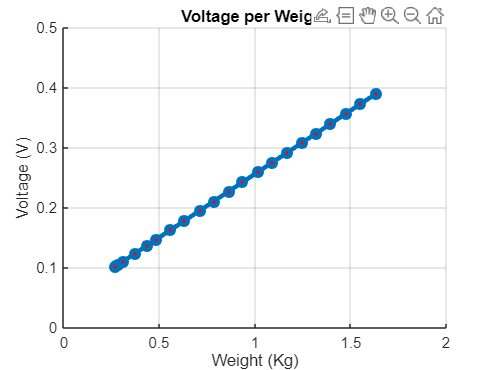


% Create the figure and plot the data
figure;
hold on;
%load("dataV");
%plot([0 500 1000 1500 2000 2500 3000 3500 4000 4500 5000 5500 6000 6500 7000 7500 8000 8500 9000 9500 10000 10500], dataV);
plot(dataW, dataV,'-o','MarkerSize',5,'MarkerFaceColor',[1 .0 .0],'LineWidth', 3);


% Set axis limits
xlim([0 2]);
ylim([0 0.5]);

% Add labels and title
xlabel('Weight (Kg)');
ylabel('Voltage (V)');
title('Voltage per Weight');
%legend('South pole without sheild','South pole with sheild','North pole without sheild','North pole with sheild')
% Turn on grid lines
grid on;

%}
